clear all
syms rGx(t) rGy(t) F1(t) F2(t) f(x)


rG=[rGx(t);rGy(t)];
F=[F1(t);F2(t)];

m=1; g=[0;0.98]; 

%Find the position of a bead sliding frictionlessly along a wire given by
%y=f(x).

%Getinng this to work for an abstract f is a project for another day. 
f(x)=x^2;


%A bead sliding doesn't really have an orientation, so axe that. 

%Newton's second. 
eq1=m*diff(rG,2)==F-m*g

$$eq1 = \left(\begin{array}{c} \frac{\partial^{2}}{\partial t^{2}}\mathrm{rGx}\left(t\right)=F_{1}\left(t\right)\\ \frac{\partial^{2}}{\partial t^{2}}\mathrm{rGy}\left(t\right)=F_{2}\left(t\right)-\frac{49}{50} \end{array}\right)$$


%No Euler

%First constraint is that the bead must always be on the wire. This is a
%position constraint. 
eq2=rGy(t)==f(rGx(t))

$$eq2 = \mathrm{rGy}\left(t\right)={\mathrm{rGx}\left(t\right)}^{2}$$


%Second constraint is that the force from the wire must be perpendicular to
%the wire.  This is the frictionless constraint. 

%The tangent vector to the wire at point x is
T=[1;diff(f)];

%Dot is complex-valued dot product, which will take complex conjugates when
%applied.  I could probably assume that rGx and rGy are real somehow, but
%instead I'll just pre-conjugate to get what I want. 

%Note -- this doesn't need to be differentiated at all! It already has the
%forces explicit in it. 
eq3=dot(conj(F),T(rGx))==0

$$eq3 = F_{1}\left(t\right)+2\,F_{2}\left(t\right)\,\mathrm{rGx}\left(t\right)=0$$


DEs=[eq1;eq3];
posnConstraints=eq2;

The unknown functions (just the base functions, not derivatives) are: F1(t),F2(t),rGx(t),rGy(t)
Initial Conditions:
Y0/YP0:
F1: -0.171892 F1t:0.000000
F2: 0.028649 F2t:0.000000
rGx: 3.000000 rGxt:-0.200000
rGy: 9.000000 rGyt:-1.200000
DrGxt: -0.200000 DrGxtt:-0.171892
DrGyt: -1.200000 DrGytt:-0.951351


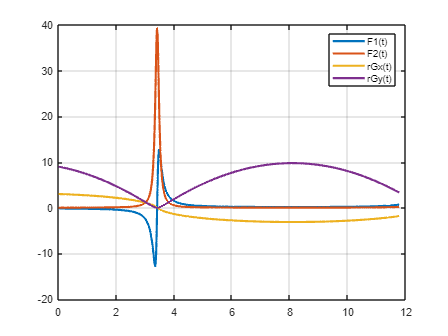

soln = struct with fields:
        t: [535×1 double]
       F1: [535×1 double]
       F2: [535×1 double]
      rGx: [535×1 double]
      rGy: [535×1 double]
    DrGxt: [535×1 double]
    DrGyt: [535×1 double]


%Pure numerics. Interstingly, this fails after a bit.  I wonder what gives?
%Is my formulation wrong?
soln=mechanicsAsDAE(DEs,posnConstraints,[],[0,20],[rGx==3,diff(rGx)==-0.2])

%Try it symbolically. 
[govDE,PP]=analyzeSystem(DEs,posnConstraints,[],[rGx,diff(rGx)]);

The unknown functions are:
F1(force)
F2(force)
rGx
rGy

Expected Number of State Variables:2


soln=timeStepODESystem(govDE,[0,30],[rGx==3,diff(rGx)==0],PP,0);

The unknown functions (just the base functions, not derivatives) are: rGx(t)


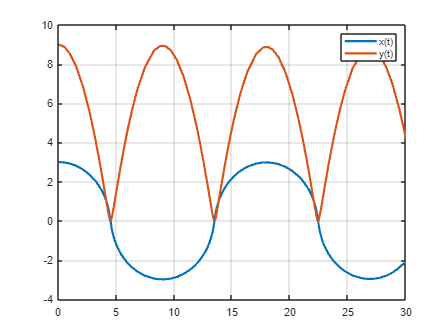

plot(soln.t,soln.rGx,soln.t,soln.rGy,'LineWidth',2); grid on; legend("x(t)","y(t)")